clc
clear

%Definir condiciones iniciales
nf = 200;

dt = 1e-11;
t = 0:dt:0.00000211;%s
%t = 0:dt:0.00000001;%s

d = 1.5e-3;%m

n = 10; %numero de protones en el haz

q = n * 1.6e-19;%C
m = n * 1.6725e-27;%kg

B = 0.9;%T
Volt = 40000;%V
E = Volt/(2*d);%V/m

wc = q*B/m;%s^-1

x0 = -d;%m
y0 = 0;%m

vx0 = 0.0000000001;%m/s
vy0 = 0;%m/s

ax0 = q*E/m * cos(wc*0);%m/s^2
ay0 = 0;%m/s^2 

T = m/2 * (vx0^2 + vy0^2) * 6.242e18;%eV

v = sqrt(vx0^2 + vy0^2);

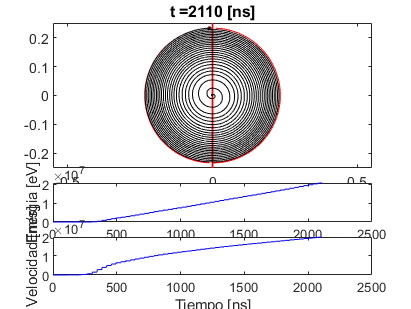

x = x0;%m
y = y0;%m

vx = vx0;%m/s
vy = vy0;%m/s

ax = ax0;%m/s^2
ay = ay0;%m/s^2 

X = zeros(1,length(t));
Y = zeros(1,length(t));
K = zeros(1,length(t));
V = zeros(1,length(t));

for i = 1:1:length(t)

    X(i) = x;%m
    Y(i) = y;%m
    K(i) = T;%eV
    V(i) = v;%m/s

    if i == 1
        figure(1)
        subplot(5,2,[1,2,3,4,5,6])
        b1 = plot(-d+0*(-1:1),-1:1,'r'); hold on;
        b2 = plot(d+0*(-1:1),-1:1,'r'); hold on;

        c1 = plot(d+0.2324*cos(-pi/2:0.05:pi/2),0.2324*sin(-pi/2:0.05:pi/2),'r'); hold on;
        c2 = plot(-d+0.2324*cos(pi/2:0.05:3*pi/2),0.2324*sin(pi/2:0.05:3*pi/2),'r'); hold on;
        xlim([-0.25 0.25])
        ylim([-0.25 0.25])
        title(strcat('t = ', num2str(t(i)*10^9),' [ns]'))
        axis equal

        subplot(5,2,[7,8])
        l2 = plot(t(1:i),K(1:i),'b'); hold on
        xlabel('Tiempo [ns]')
        ylabel('Energia [eV]')

        subplot(5,2,[9,10])
        l3 = plot(t(1:i),V(1:i),'b'); hold on
        xlabel('Tiempo [ns]')
        ylabel('Velocidad [m/s]')
    else
        set(b1,'XData',-d+0*(-1:1),'YData',-1:1)
        set(b2,'XData',d+0*(-1:1),'YData',-1:1)

        set(c1,'XData',d+0.2324*cos(-pi/2:0.05:pi/2),'YData',0.2324*sin(-pi/2:0.05:pi/2))
        set(c2,'XData',-d+0.2324*cos(pi/2:0.05:3*pi/2),'YData',0.2324*sin(pi/2:0.05:3*pi/2))
        title(strcat('t = ', num2str(t(i)*10^9),' [ns]'))

        set(l2,'XData',t(1:i)*10^9,'YData',K(1:i))

        set(l3,'XData',t(1:i)*10^9,'YData',V(1:i))
    end

    if abs(x)<=d && y>=0 
    
        if i == 1
            figure(1)
            subplot(5,2,[1,2,3,4,5,6])
            p1 = plot(x,y,'.b'); hold on;
            l1 = plot(X(1:i),Y(1:i),'b');hold on;
            axis equal
        elseif mod(i,nf) == 0
            set(p1,'XData',x,'YData',y,'Color',[0 0 1])
            set(l1,'XData',X(1:i),'YData',Y(1:i),'Color',[0 0 0])
            pause(0.0001)
        end
        
%        ax = q/m * E*cos(wc*(t(i) + 2*d/v));
        ax = q/m * E* 4/pi * ( ...
            cos((t(i) + 2*d/v)*(wc)) - ...
            1/3*cos(3*(t(i) + 2*d/v)*(wc)) + ...
            1/5*cos(5*(t(i) + 2*d/v)*(wc)) - ...
            1/7*cos(7*(t(i) + 2*d/v)*(wc)) + ...
            1/9*cos(9*(t(i) + 2*d/v)*(wc)) - ...
            1/11*cos(11*(t(i) + 2*d/v)*(wc)) + ...
            1/13*cos(13*(t(i) + 2*d/v)*(wc)) - ...
            1/15*cos(15*(t(i) + 2*d/v)*(wc)) + ...
            1/17*cos(17*(t(i) + 2*d/v)*(wc)) - ...
            1/19*cos(19*(t(i) + 2*d/v)*(wc)) + ...
            1/21*cos(21*(t(i) + 2*d/v)*(wc)));
        ay = 0;

    elseif abs(x) < d && y<0
        
        if i == 1
            figure(1)
            subplot(5,2,[1,2,3,4,5,6])
            p1 = plot(x,y,'.r'); hold on;
            l1 = plot(X(1:i),Y(1:i),'r');hold on;
        elseif mod(i,nf) == 0
            set(p1,'XData',x,'YData',y,'Color',[1 0 0])
            set(l1,'XData',X(1:i),'YData',Y(1:i),'Color',[0 0 0])
            pause(0.0001)
        end

%        ax = q/m * E*cos(wc*(t(i) + 2*d/v));
        ax = q/m * E* 4/pi * ( ...
            cos((t(i) + 2*d/v)*(wc)) - ...
            1/3*cos(3*(t(i) + 2*d/v)*(wc)) + ...
            1/5*cos(5*(t(i) + 2*d/v)*(wc)) - ...
            1/7*cos(7*(t(i) + 2*d/v)*(wc)) + ...
            1/9*cos(9*(t(i) + 2*d/v)*(wc)) - ...
            1/11*cos(11*(t(i) + 2*d/v)*(wc)) + ...
            1/13*cos(13*(t(i) + 2*d/v)*(wc)) - ...
            1/15*cos(15*(t(i) + 2*d/v)*(wc)) + ...
            1/17*cos(17*(t(i) + 2*d/v)*(wc)) - ...
            1/19*cos(19*(t(i) + 2*d/v)*(wc)) + ...
            1/21*cos(21*(t(i) + 2*d/v)*(wc)));
        ay = 0;

    elseif abs(x) > d
        if i == 1
            figure(1)
            subplot(5,2,[1,2,3,4,5,6])
            p1 = plot(x,y,'.k'); hold on;
            l1 = plot(X(1:i),Y(1:i),'k');hold on;
        elseif mod(i,nf) == 0
            set(p1,'XData',x,'YData',y,'Color',[0 0 0])
            set(l1,'XData',X(1:i),'YData',Y(1:i),'Color',[0 0 0])
            pause(0.0001)
        end

        ax = wc*vy;
        ay = -wc*vx;
    end

    vx = vx + ax*dt;%m/s
    vy = vy + ay*dt;%m/s
    
    x = x + vx*dt;%m
    y = y + vy*dt;%m/s
    
    T = m/2 * (vx^2 + vy^2) * 6.242e18;%eV

    v = sqrt(vx^2 + vy^2);
end